function [r, el, az] = transformSatOrigin(obs_lat, obs_lon, sat_lat, sat_lon, r_sat)
    re = 6.378e6;

    r_x = r_sat - (re .* sin((pi/2)-obs_lat) .* cos(obs_lon-sat_lon));
    r_y = -re .* sin((pi/2)-obs_lat) .* sin(obs_lon-sat_lon);
    r_z = re .* cos((pi/2)-obs_lat);
    
    r = sqrt(r_x.^2 + r_y.^2 + r_z.^2);
    az = atan(r_y ./ r_x);
    el = acos(r_z ./ r);
end

function af = arrayFactor(ant_array, beta, theta, phi)
    r_hat_x = sin(theta) .* cos(phi);
    r_hat_y = sin(theta) .* sin(phi);
    r_hat_z = cos(theta);

    [M, N] = size(ant_array);
    af = zeros(size(theta));
    for y = 0:1:N-1
        for z = 0:1:M-1
            r_dot_r_hat = r_hat_y * y + r_hat_z * z;
            af = af + ant_array(z+1, y+1) * exp(-1i * (pi * r_dot_r_hat + beta));
        end
    end

    af = abs(af);
end

function rx_power = calcReceivePower(rx_gain, tx_gain, tx_power, k, distance)
    path_loss = 20 * log10(k * distance);
    rx_power = tx_power + tx_gain + rx_gain - path_loss;
end

function plotRadiationPattern(array, N)
    [Theta, Phi] = meshgrid(linspace(0, pi, N), linspace(-pi, pi, N));
    af = arrayFactor(array, 0, Theta, Phi);
    r = af;
    
    % Convert spherical to Cartesian coordinates
    X = r .* sin(Theta) .* cos(Phi);
    Y = r .* sin(Theta) .* sin(Phi);
    Z = r .* cos(Theta);
    
    % Create the spherical surface plot
    surf(X, Y, Z);
    
    % Customize the plot
    title('Radiation Pattern');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    axis equal;
    colormap jet;
    shading interp;
end

function plotMaskedHeatmap(data, mask)
    data = data .* mask;
    data = max(data - min(data(data ~= 0)), 0);
    data = data * 223 / max(data, [], "all");
    data = (data + 32) .* mask;
    imagesc(data); axis equal;
end

function new_pop = nextGeneration(pop, scores)
    mutation_q = 0.75;

    [~, idx] = sort(scores, "descend");
    pop = pop(:, :, idx);
    new_pop = pop;
    
    idx = 3;
    for mother = 1:5
        for father = mother+1:5
            new_pop(:, :, idx) = pop(:, :, mother) | pop(:, :, father);
            idx = idx + 1;
            if idx > 10
                break;
            end
        end
        if idx > 10
            break;
        end
    end

    mutations = randn(size(new_pop)) > mutation_q;
    new_pop = (new_pop & ~mutations) | (~new_pop & mutations);
end

load("GAmap.mat");
re = 6.378e6;
r_sat = 42.400e6;
freq = 30e9;
k = 2 * pi / (3e8 / freq);
tx_power = 60;
rx_gain = 10;

sat_lat = 0 * pi / 180;
sat_lon = -83.5* pi / 180;

bs_lat = 33 * pi / 180;
bs_lon = -83.75 * pi / 180;

[r, bs_el, bs_az] = transformSatOrigin(bs_lat, bs_lon, sat_lat, sat_lon, r_sat);

data = GA.data > 128;

lats = GA.lat * -1 * pi / 180;
lons = GA.lon * pi / 180; 

[dist, el, az] = transformSatOrigin(lats, lons, sat_lat, sat_lon, r_sat);
el = el - bs_el + pi/2;
az = az - bs_az;

%array = ones(30,30) > 0;
%tx_gain = 20*log10(arrayFactor(array, 0, el, az));
%rx_power = calcReceivePower(rx_gain, tx_gain, tx_power, k, dist);

%plotRadiationPattern(array, 100);

array_pop = (randn(30, 30, 10) > 0.15) * 1.0;
%array_pop(:, :, 1) = ones(30, 30);
%array_pop(:, :, 2) = toeplitz((1:1:30 < 15) * 1.0);
scores = zeros(1, 10);

sol = zeros(30);
sol_score = 0;

for i = 1:15
    for j = 1:10
        tx_gain = 20*log10(arrayFactor(array_pop(:, :, j), 0, el, az));
        rx_power = calcReceivePower(rx_gain, tx_gain, tx_power, k, dist);
        avg = mean2(rx_power);
        exclusion_rate = sum((rx_power < avg) .* (data < 1) , "all") / sum(data < 1, "all");
        inclusion_rate = sum((rx_power >= avg) .* data, "all") / sum(data, "all");
        scores(j) = 65*exclusion_rate + 35*inclusion_rate;
        65*exclusion_rate + 35*inclusion_rate
        count = j + (i-1) * 10
    end
    
    if max(scores) > sol_score
        [sol_score, idx] = max(scores)
        sol = array_pop(:, :, idx)
    end
    array_pop = nextGeneration(array_pop, scores);
end

ans = 78.7686

count = 1

ans = 79.7093

count = 2

ans = 80.0544

count = 3

ans = 79.5756

count = 4

ans = 78.7129

count = 5

ans = 79.5719

count = 6

ans = 80.0944

count = 7

ans = 79.2498

count = 8

ans = 79.5839

count = 9

ans = 79.4295

count = 10

sol_score = 80.0944

idx = 7

sol =      1     0     0     1     0     0     0     0     0     0     0     1     0     0     1     0     1     0     1     1     1     1     0     1     1     1     0     1     0     0
     0     1     0     0     1     1     1     1     0     1     0     0     1     0     0     0     1     1     0     1     0     1     0     0     0     0     1     0     1     0
     0     1     1     1     1     0     0     0     0     0     1     1     1     1     0     0     1     0     1     0     0     0     0     1     0     1     1     0     0     1
     0     0     1     0     1     0     1     0     0     0     0     0     1     0     1     0     1     0     1     1     0     0     1     1     1     0     0     0     1     0
     0     0     1     0     0     1     0     1     0     1     0     0     0     1     0     1     1     0     0     0     0     0     0     1     1     0     1     0     0     0
     1     1     1     0     0     0     0     1     1     1     0     0     1     1     

ans = 80.0291

count = 11

ans = 80.1883

count = 12

ans = 79.9337

count = 13

ans = 79.0359

count = 14

ans = 80.0924

count = 15

ans = 79.5270

count = 16

ans = 79.8111

count = 17

ans = 79.8273

count = 18

ans = 79.5439

count = 19

ans = 79.7852

count = 20

sol_score = 80.1883

idx = 2

sol = 30×30 logical array
   1   1   0   0   0   0   1   1   1   0   0   0   0   1   0   0   0   0   1   0   1   0   0   0   0   0   0   1   1   1
   1   0   0   0   0   0   0   0   0   0   1   1   1   1   0   1   1   1   0   0   1   1   0   0   0   1   0   0   1   0
   1   1   0   0   0   0   1   1   0   1   0   1   1   1   0   0   0   1   0   0   1   1   1   1   0   1   1   0   0   0
   0   1   1   0   1   0   1   1   1   0   0   0   0   0   1   0   1   0   0   0   1   0   1   1   1   1   0   1   1   0
   1   1   0   0   1   0   1   1   0   0   1   1   1   0   0   1   0   1   1   1   0   0   1   0   0   1   0   1   0   1
   0   1   0   0   0   0   1   0   0   1   0   1   1   0   0   1   1   1   0   1   0   0   0   1   1   0   1   0   1   0
   0   0   0   0   1   0   1   0   1   0   0   0   0   1   1   0   1   1   1   0   0   1   0   1   1   0   0   1   1   0
   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   0   1   0   0   0   1   1   0   1   0
   1  

ans = 80.3705

count = 21

ans = 79.6147

count = 22

ans = 79.6304

count = 23

ans = 79.8742

count = 24

ans = 80.0630

count = 25

ans = 79.1596

count = 26

ans = 79.7691

count = 27

ans = 79.6761

count = 28

ans = 79.6170

count = 29

ans = 79.6519

count = 30

sol_score = 80.3705

idx = 1

sol = 30×30 logical array
   1   1   0   0   0   0   0   1   1   1   0   0   0   0   0   0   1   1   1   0   1   0   0   0   1   0   1   1   1   1
   1   0   1   0   0   0   0   0   1   0   1   1   0   1   0   0   1   0   1   0   1   0   0   0   0   1   0   0   1   0
   0   1   0   0   0   0   1   1   0   1   0   1   1   1   0   1   1   0   0   0   1   1   1   0   0   1   0   0   0   0
   0   1   1   0   1   1   1   1   0   0   0   0   1   0   1   0   1   1   1   0   1   1   1   0   1   1   0   1   1   0
   1   1   0   0   0   0   0   0   0   0   1   0   1   0   0   1   1   0   1   1   0   0   1   0   0   1   0   1   0   1
   0   1   0   0   0   0   1   0   0   1   1   1   1   0   0   0   1   1   0   1   0   0   0   1   0   0   1   0   1   1
   0   0   0   0   1   1   1   0   1   1   0   1   0   1   1   1   0   1   1   0   0   0   0   0   1   0   1   1   1   0
   1   1   0   1   0   1   0   1   1   0   0   0   0   0   0   1   0   0   1   1   0   1   0   0   1   1   1   0   1   0
   1  

ans = 79.7337

count = 31

ans = 79.8931

count = 32

ans = 80.1073

count = 33

ans = 79.8391

count = 34

ans = 80.1304

count = 35

ans = 79.7675

count = 36

ans = 79.6573

count = 37

ans = 79.9245

count = 38

ans = 79.7863

count = 39

ans = 80.2400

count = 40

ans = 80.0052

count = 41

ans = 80.1313

count = 42

ans = 79.8474

count = 43

ans = 79.5958

count = 44

ans = 79.6875

count = 45

ans = 79.7899

count = 46

ans = 80.1647

count = 47

ans = 80.4688

count = 48

ans = 79.6863

count = 49

ans = 79.6210

count = 50

sol_score = 80.4688

idx = 8

sol = 30×30 logical array
   0   1   1   0   0   1   0   1   0   0   1   1   1   1   1   0   1   1   1   1   1   1   0   1   0   1   0   1   1   1
   0   1   1   0   0   0   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   0   1   0   1   1   1   1   1
   0   1   1   1   1   1   0   1   0   1   0   1   1   1   1   0   1   1   1   1   1   1   1   1   0   1   1   1   1   1
   0   0   0   1   1   1   0   1   0   1   1   0   1   1   1   1   1   0   1   1   1   1   1   1   1   0   1   1   1   1
   0   1   0   1   1   0   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   0   1   0   1   1   1
   1   1   1   1   1   1   0   1   1   1   1   0   1   0   1   1   1   0   0   1   1   1   0   1   1   1   1   1   1   1
   1   0   0   1   0   1   1   0   1   1   0   0   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   0   0   1
   0   0   1   1   1   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   0   0   0
   1  

ans = 80.4770

count = 51

ans = 79.4504

count = 52

ans = 80.0117

count = 53

ans = 80.1804

count = 54

ans = 79.7159

count = 55

ans = 79.9125

count = 56

ans = 80.4288

count = 57

ans = 79.5453

count = 58

ans = 80.1386

count = 59

ans = 79.2412

count = 60

sol_score = 80.4770

idx = 1

sol = 30×30 logical array
   1   1   0   0   0   0   0   1   1   0   1   1   0   1   1   1   1   1   1   1   1   1   0   1   0   1   1   0   1   1
   0   1   1   0   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   0   1   1   1
   0   1   0   1   0   0   0   1   0   0   1   1   0   1   1   1   1   1   0   0   1   1   1   1   0   1   1   1   0   1
   0   0   0   1   1   1   1   1   0   0   0   0   1   1   0   1   0   0   0   0   1   0   1   1   1   0   1   1   1   0
   0   0   0   0   1   0   1   1   0   0   1   1   1   1   0   1   0   1   1   1   1   1   1   1   0   0   0   1   1   0
   0   1   0   0   1   1   0   1   1   1   1   0   1   0   1   1   1   0   0   1   1   1   0   1   0   1   1   0   0   1
   1   0   0   1   0   0   0   0   1   1   0   0   1   1   0   0   1   0   0   1   0   1   1   1   1   1   0   0   0   1
   1   0   0   1   1   1   1   1   1   0   0   0   1   1   0   0   1   1   1   1   1   0   0   1   0   1   0   1   0   0
   0  

ans = 79.3946

count = 61

ans = 80.2152

count = 62

ans = 79.9739

count = 63

ans = 80.0353

count = 64

ans = 80.1736

count = 65

ans = 79.6613

count = 66

ans = 79.3842

count = 67

ans = 79.6643

count = 68

ans = 79.4060

count = 69

ans = 79.7423

count = 70

ans = 79.7697

count = 71

ans = 80.0540

count = 72

ans = 79.9855

count = 73

ans = 79.6393

count = 74

ans = 79.9384

count = 75

ans = 79.1095

count = 76

ans = 79.5527

count = 77

ans = 79.5979

count = 78

ans = 80.0695

count = 79

ans = 79.6009

count = 80

ans = 80.1648

count = 81

ans = 80.0328

count = 82

ans = 79.8947

count = 83

ans = 79.7754

count = 84

ans = 79.7622

count = 85

ans = 80.0162

count = 86

ans = 79.7910

count = 87

ans = 80.1411

count = 88

ans = 79.4053

count = 89

ans = 80.2595

count = 90

ans = 79.4785

count = 91

ans = 80.1663

count = 92

ans = 79.5657

count = 93

ans = 79.9928

count = 94

ans = 80.0006

count = 95

ans = 79.7520

count = 96

ans = 79.7630

count = 97

ans = 79.7467

count = 98

ans = 79.7709

count = 99

ans = 79.7611

count = 100

ans = 79.8851

count = 101

ans = 79.7374

count = 102

ans = 79.3197

count = 103

ans = 79.6977

count = 104

ans = 79.6726

count = 105

ans = 79.4505

count = 106

ans = 80.1242

count = 107

ans = 79.8758

count = 108

ans = 79.3037

count = 109

ans = 79.9276

count = 110

ans = 79.8407

count = 111

ans = 79.6539

count = 112

ans = 79.4989

count = 113

ans = 79.5613

count = 114

ans = 79.5778

count = 115

ans = 79.8441

count = 116

ans = 79.7928

count = 117

ans = 79.8451

count = 118

ans = 79.6927

count = 119

ans = 79.5119

count = 120

ans = 79.4305

count = 121

ans = 79.4145

count = 122

ans = 79.4386

count = 123

ans = 80.0283

count = 124

ans = 79.7003

count = 125

ans = 79.3966

count = 126

ans = 79.8762

count = 127

ans = 79.5079

count = 128

ans = 79.9339

count = 129

ans = 79.9667

count = 130

ans = 80.0968

count = 131

ans = 79.7469

count = 132

ans = 79.3653

count = 133

ans = 79.6688

count = 134

ans = 79.9027

count = 135

ans = 79.8045

count = 136

ans = 79.7458

count = 137

ans = 79.9405

count = 138

ans = 80.0282

count = 139

ans = 79.9039

count = 140

ans = 79.9434

count = 141

ans = 80.2054

count = 142

ans = 80.0194

count = 143

ans = 79.9194

count = 144

ans = 79.7168

count = 145

ans = 80.3176

count = 146

ans = 80.0186

count = 147

ans = 80.1043

count = 148

ans = 79.4693

count = 149

ans = 79.5760

count = 150

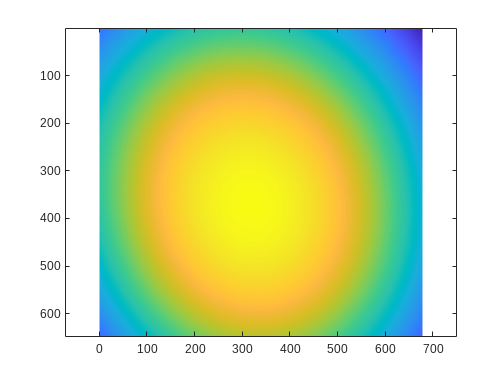


tx_gain = 20*log10(arrayFactor(sol, 0, el, az));
rx_power = calcReceivePower(rx_gain, tx_gain, tx_power, k, dist);

imagesc(10.^(rx_power/10)); axis equal;

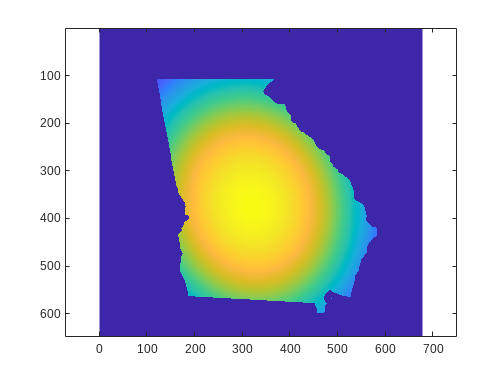


plotMaskedHeatmap(10.^(rx_power/10), data);